%% Example usage

n = 64;

A_blur = blur_operator(n, 2.0)

A_blur =     0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0001    0.0004    0.0022    0.0088
    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0001    0.0004

A_down = downsample_operator(n, 2)

A_down =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0    

A_rank = rank_deficient_operator(n, 12)

A_rank =    -0.0591    0.0144   -0.0190   -0.0571    0.0334    0.0034    0.1365   -0.0775    0.0991    0.0073   -0.0508    0.0171    0.0097    0.0081   -0.0646    0.1720   -0.0181    0.0275    0.0101   -0.0067    0.0020    0.0545    0.1481    0.0479   -0.0523    0.0503    0.0096   -0.0240    0.0839    0.0376   -0.0902    0.0093    0.0517    0.0389    0.1507    0.0125    0.0392   -0.0812   -0.0643   -0.0583   -0.0598   -0.0211    0.0435   -0.0449    0.0500   -0.0408   -0.0624    0.0848    0.0779    0.0675
    0.0940   -0.0194   -0.0083    0.0751    0.0745   -0.0597   -0.0556    0.0154   -0.0229    0.0834   -0.0446   -0.0215    0.0470    0.0090   -0.0039   -0.1088   -0.0087   -0.0141   -0.1066   -0.0042    0.0956   -0.0515   -0.0467   -0.0821   -0.0109    0.0607    0.0209    0.0092   -0.0309   -0.0754    0.0753    0.0468    0.0042   -0.0009    0.0703    0.0150    0.0024   -0.0391    0.0074   -0.0083   -0.0283    0.0632   -0.0573    0.0022    0.0740    0.0644    0.0010   -0.0252   -0.0038

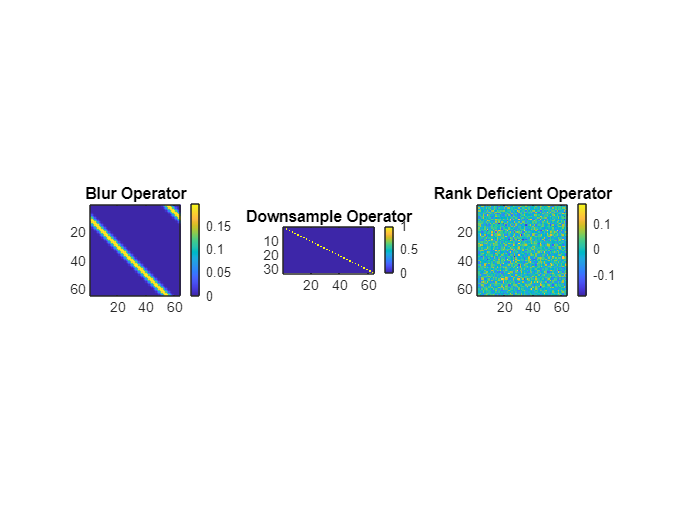


figure;
subplot(1,3,1); imagesc(A_blur); axis image;
title('Blur Operator'); colorbar;

subplot(1,3,2); imagesc(A_down); axis image;
title('Downsample Operator'); colorbar;

subplot(1,3,3); imagesc(A_rank); axis image;
title('Rank Deficient Operator'); colorbar;

function A = blur_operator(n, sigma, kernel_radius)
% BLUR_OPERATOR  Circulant Gaussian blur matrix

    if nargin < 3
        kernel_radius = 10;
    end

    ksize = 2 * kernel_radius + 1;
    k = gaussian_kernel(ksize, sigma);

    A = zeros(n, n);

    for i = 1:n
        for j = 1:n
            shift = mod(i - j, n);
            if shift < ksize
                A(i, j) = k(shift + 1);
            end
        end
    end
end

function A = downsample_operator(n, factor)
% DOWNSAMPLE_OPERATOR  Downsampling matrix

    if nargin < 2
        factor = 2;
    end

    m = floor(n / factor);
    A = zeros(m, n);

    for i = 1:m
        A(i, (i-1)*factor + 1) = 1.0;
    end
end

function A = rank_deficient_operator(n, r)
% RANK_DEFICIENT_OPERATOR  Rank-deficient matrix

    [U, ~, V] = svd(randn(n, n), 'econ');

    s = linspace(1.0, 0.1, n);
    s(r+1:end) = 0.0;

    A = U * diag(s) * V';
end

function k = gaussian_kernel(sz, sigma)
% GAUSSIAN_KERNEL  1D Gaussian kernel

    idx = -(floor(sz/2)) : floor(sz/2);
    k = exp(-0.5 * (idx / sigma).^2);
    k = k / sum(k);
end